Example of UTS*Area load cases 

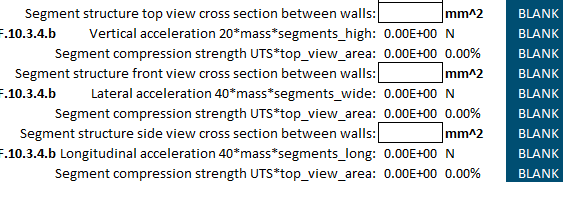

Battery Coverved Volume dimensions(what area the casing must enclose)

https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf


EneModWidth = 20.3/1000;%width(ex:65mm(cell)+module sides)
EneSegHeight =  105.6/1000;%height(m)
EneModDepth = 69.5/1000;
ModuleWeight = 278/1000;%weight in kg
SegmentCasingHeight = 0.10555;%m

EneSegmentDepth = 6*EneModDepth + 0.082 -0.022%num moduleSs*moduleDepth*mmtoinches + flange added length - hole locatoin

EneSegmentDepth = 0.4770


EneSegmentWidth = EneModWidth * 4

EneSegmentWidth = 0.0812

SegmentWeight = ModuleWeight*23;
CasingThickness = 1/8*25.4/1000;

TopCrossSecArea = EneSegmentDepth*CasingThickness*2

TopCrossSecArea = 0.0030

TopCrossSecForce = SegmentWeight*20*9.8%in newtons

TopCrossSecForce = 1.2532e+03

TopStress = TopCrossSecForce/TopCrossSecArea

TopStress = 4.1375e+05


WidthCrossSecArea = EneSegmentDepth*CasingThickness*2

WidthCrossSecArea = 0.0030

WidthCrossSecForce = 6*SegmentWeight*40*9.8%in newtons

WidthCrossSecForce = 1.5039e+04

WidthStress = WidthCrossSecForce/WidthCrossSecArea

WidthStress = 4.9650e+06



DepthCrossSecArea = EneSegmentWidth*CasingThickness*2 + EneSegHeight*CasingThickness*2

DepthCrossSecArea = 0.0012

DepthCrossSecForce = SegmentWeight * 40 * 9.8;
DepthStress = DepthCrossSecForce/DepthCrossSecArea

DepthStress = 2.1130e+06

Bolt calculations

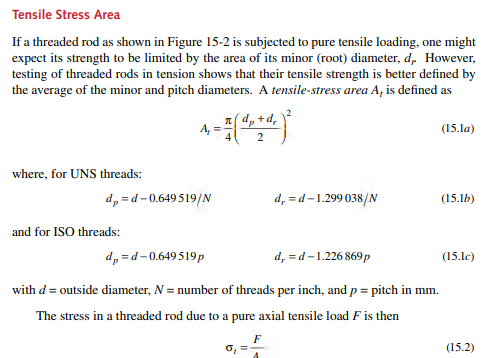

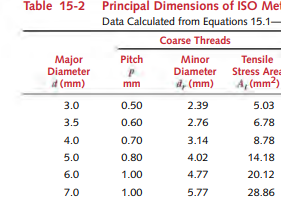

 dia = 6;
 pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000

ABTMeters = 2.0123e-05


exampleGr5Tensile = 827370875%pa 

exampleGr5Tensile = 827370875

MaxForce = exampleGr5Tensile*ABTMeters %newtons

MaxForce = 1.6649e+04

Tear out calcs

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

strength values from here

psiTopPascal = 6894.76;
garoliteStrength = 38000*psiTopPascal;
garoliteThickness = 6.35/1000;
BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge

maxTearoutForce = BoltDistanceFromEdge*garoliteThickness*garoliteStrength

maxTearoutForce = 1.3310e+04

fr4BondStrength = 2200*psiTopPascal

fr4BondStrength = 15168472

MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength

MinFlangeBondArea = 1.6524e-04

FlangeBondSF = 1;%when one side goes into tension the other should go into compression. 
MinAdhesivedAreaForFlange = MinFlangeBondArea * FlangeBondSF 

MinAdhesivedAreaForFlange = 1.6524e-04


DepthRestrictingBondArea = garoliteThickness * 80/1000

DepthRestrictingBondArea = 5.0800e-04

SideBondArea = 0.02* garoliteThickness*2;


Deflection from forces and pressdown 

garoliteFlexuralModulus = 2400* 1000 * psiTopPascal;
Packload = TopCrossSecForce ;
vmax = Packload * (EneSegmentDepth^4)/384/(garoliteFlexuralModulus)/((0.08*0.00635^3)/12)

vmax = 0.0060

Deflection of width module hold down beams

Packload = TopCrossSecForce + 500;
vmax2 = Packload * (EneSegmentWidth^4)/384/(garoliteFlexuralModulus)/((0.0168*0.00635^3)/12)

vmax2 = 3.3462e-05

Euler-Johnson buckilng limits

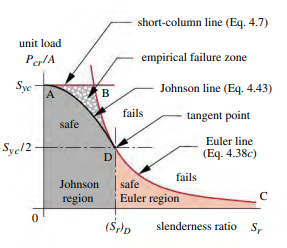




MomentOfInertiaSideWalls = 2*( (EneSegmentWidth/2+garoliteThickness/2)^2 * CasingThickness*EneSegHeight) + (garoliteThickness^3*SegmentCasingHeight/12)

MomentOfInertiaSideWalls = 1.2872e-06

% half width to get to walls + half of garolite thickness = centroid
% distance away, * area sidewall + garolite thickness^3(height) * segment height(width) 


MomentOfInertiaBottom = (garoliteThickness/2 + EneSegHeight/2)^2 * CasingThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaBottom = 8.0950e-07


MomentOfInertiaLid = (garoliteThickness/2 + EneSegHeight/2+(15/1000))^2 * CasingThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaLid = 1.3004e-06


ixx = MomentOfInertiaLid + MomentOfInertiaBottom + MomentOfInertiaSideWalls

ixx = 3.3972e-06

RadiusOfGyration = sqrt(ixx/DepthCrossSecArea)

RadiusOfGyration = 0.0535


srCasing = EneSegmentDepth/RadiusOfGyration

srCasing = 8.9132


SrPointD = pi*sqrt(2*garoliteFlexuralModulus/garoliteStrength)

SrPointD = 35.3085


prJohnson = DepthCrossSecArea *(garoliteStrength-(1/garoliteFlexuralModulus *(garoliteStrength*srCasing/2/pi)^2))

prJohnson = 3.0088e+05

Thermal